Now importing...Could not import chanlocs: Reference to non-existent field 'channels'.
done.
eeg_checkset warning: no field label in channel location structure, removing it
         number of channels. Channel information have been removed.
Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Galina\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one


Retrieving plugin versions from server...
Retreiving download statistics...


EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)


EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.5 available


EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "erplab" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


You are using the latest version of EEGLAB.
Now importing...Could not import chanlocs: Reference to non-existent field 'channels'.
done.
eeg_checkset warning: no field label in channel location structure, removing it


         number of channels. Channel information have been removed.
pop_eegfiltnew() - performing 43 point lowpass filtering.
pop_eegfiltnew() - transition band width: 10 Hz
pop_eegfiltnew() - passband edge(s): 40 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 45 Hz


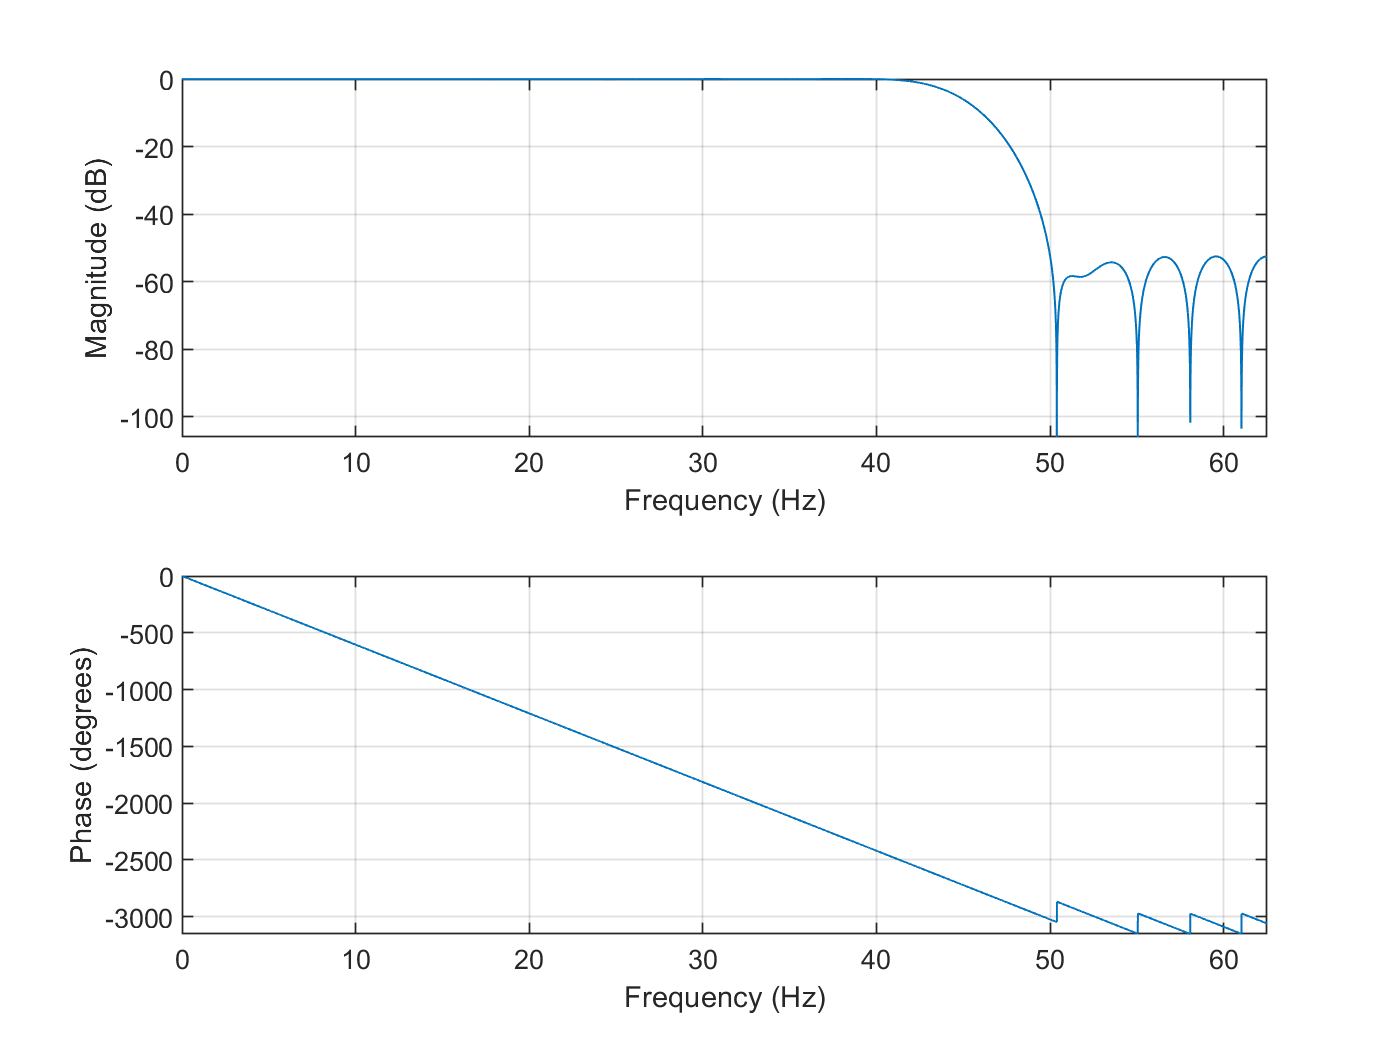

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
pop_eegfiltnew() - performing 827 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.5 Hz
pop_eegfiltnew() - passband edge(s): 0.5 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.25 Hz


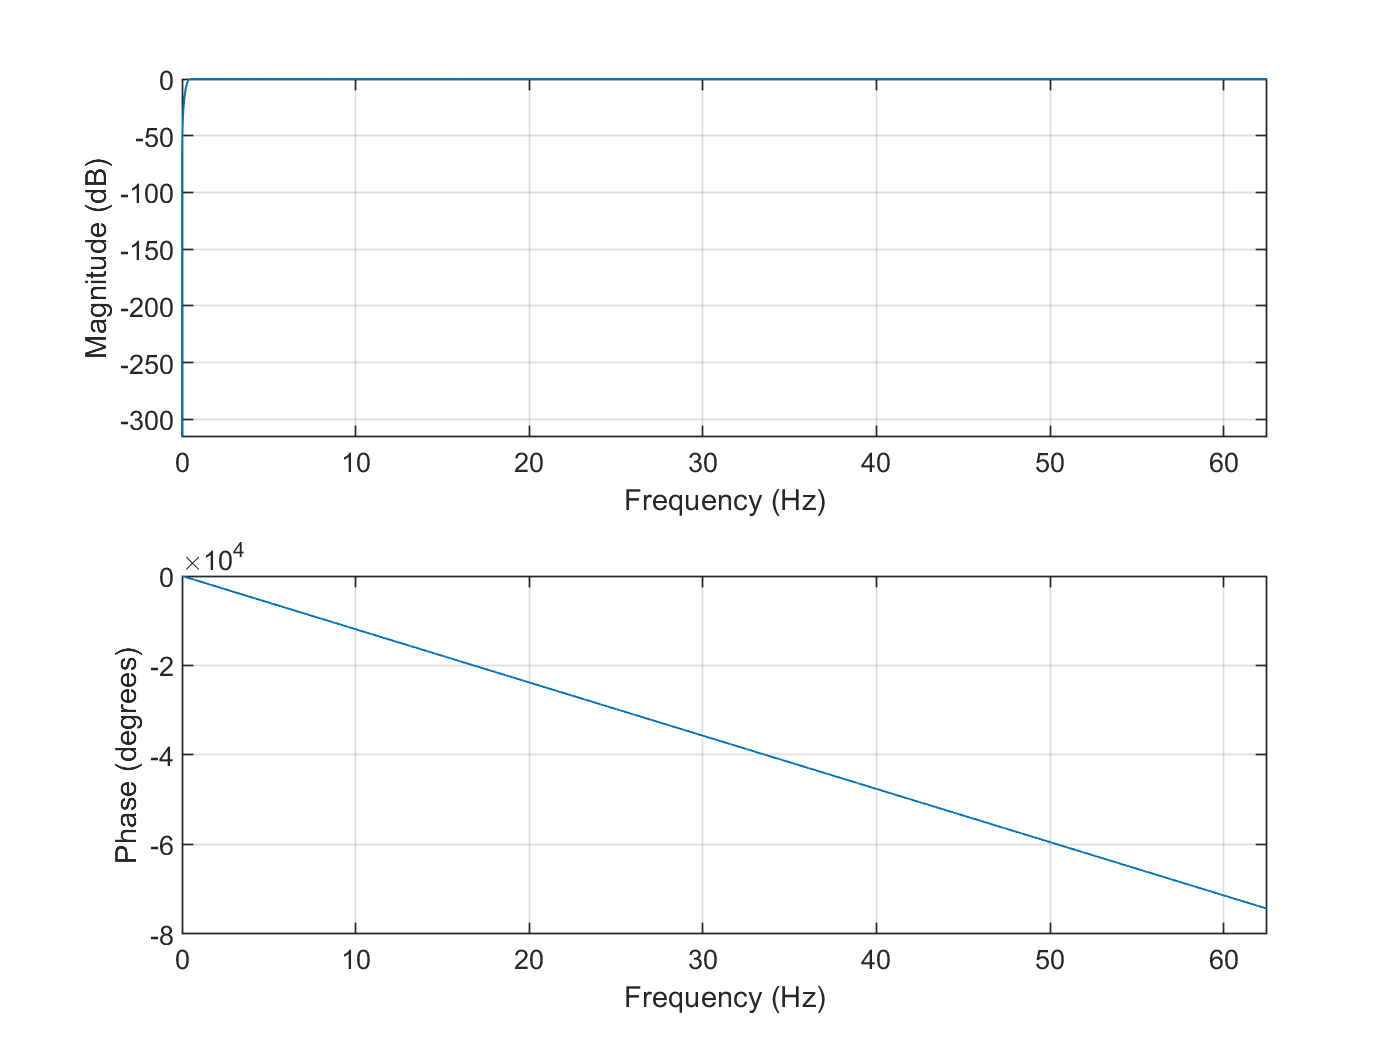

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Channels to be filtered : [ 1:15]



Stop-band (Parks-McClellan Notch) filtering input data (fc = [ 50 50]' Hz), please wait...


Done.  What's next?



% Week 5 Assignment

%% Add file paths

addpath(genpath('C:\Toolboxes'))
addpath(genpath('C:\GitHub\BCI4ALS-MI'))
addpath(genpath('C:\Toolboxes\liblsl-Matlab'))
addpath(genpath('C:\Recordings'))

%% Collect data
%lib = lsl_loadlib(); version = lsl_library_version(lib);
%eeglab
%MI1_offline_training();

%% Define subject ID
subjectID = "Sub1_20211104"; % as entered at time of recording

%% read data, output raw and preprocessed files
[EEG_raw, EEG_clean] = open_and_preprocess(subjectID);


%% plot raw data x voltage
% eegplot(EEG.data, 'srate', EEG.srate, 'eloc_file', strcat(recordingFolder, '\EEG_chans.mat'))   
%% PSD
pop_spectopo(EEG_raw)

Topographic plot options ignored. First import a channel location file
To plot a single channel, use channel property menu or the following call
  >> figure; chan = 1; spectopo(EEG.data(chan,:,:), EEG.pnts, EEG.srate);


Pop_spectopo: finding data discontinuities
Selecting the first 50.0% of data for analysis...
Computing spectra (window length 125; fft length: 125; overlap 0):
................


Click on each trace for channel/component index


ans = 'figure; pop_spectopo(EEG, 1, [0  291952], 'EEG' , 'percent', 50, 'freqrange',[2 25],'electrodes','off');'


%% LaPlacian on clean data file
clean_data_mat = EEG_clean.data;
% probelm with importing channel labels; import manually
% maybe problem in channel 1 (and no channel 4 for sure)
% so no c3 at the moment

c4_num = 2; % channel number
four_close_c4 = [5 7 9 11]; % four electrodes closest to electrode C4
% spatial laplacian- subtracting from channel c4 the mean of the
% closest channels
c4 = clean_data_mat(c4_num,:); % data from electrode C4 only
lap_c4 = c4 - mean(clean_data_mat(four_close_c4,:));

% convert sampling to time
num_samples = length(c4); % number of samples
srate = EEG_clean.srate; % sampling rate
total_ms = num_samples / srate * 1000;
timeVec = 0:8:total_ms-1;

% plot laPlacian before and after
plot(timeVec,c4, 'LineWidth', 2);
hold on;
plot(timeVec,lap_c4,'LineWidth', 2);
xlabel('Time (ms)'); ylabel('Amplitude (mV)')
title('C4 before and after Spatial Laplacian');
legend('c4', 'c4 - after laplacian');
xlim([0, 1500]);

%% plot cleaned and uncleaned data

% plot raw data
eegplot(EEG_raw.data)

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true



ans =

     []



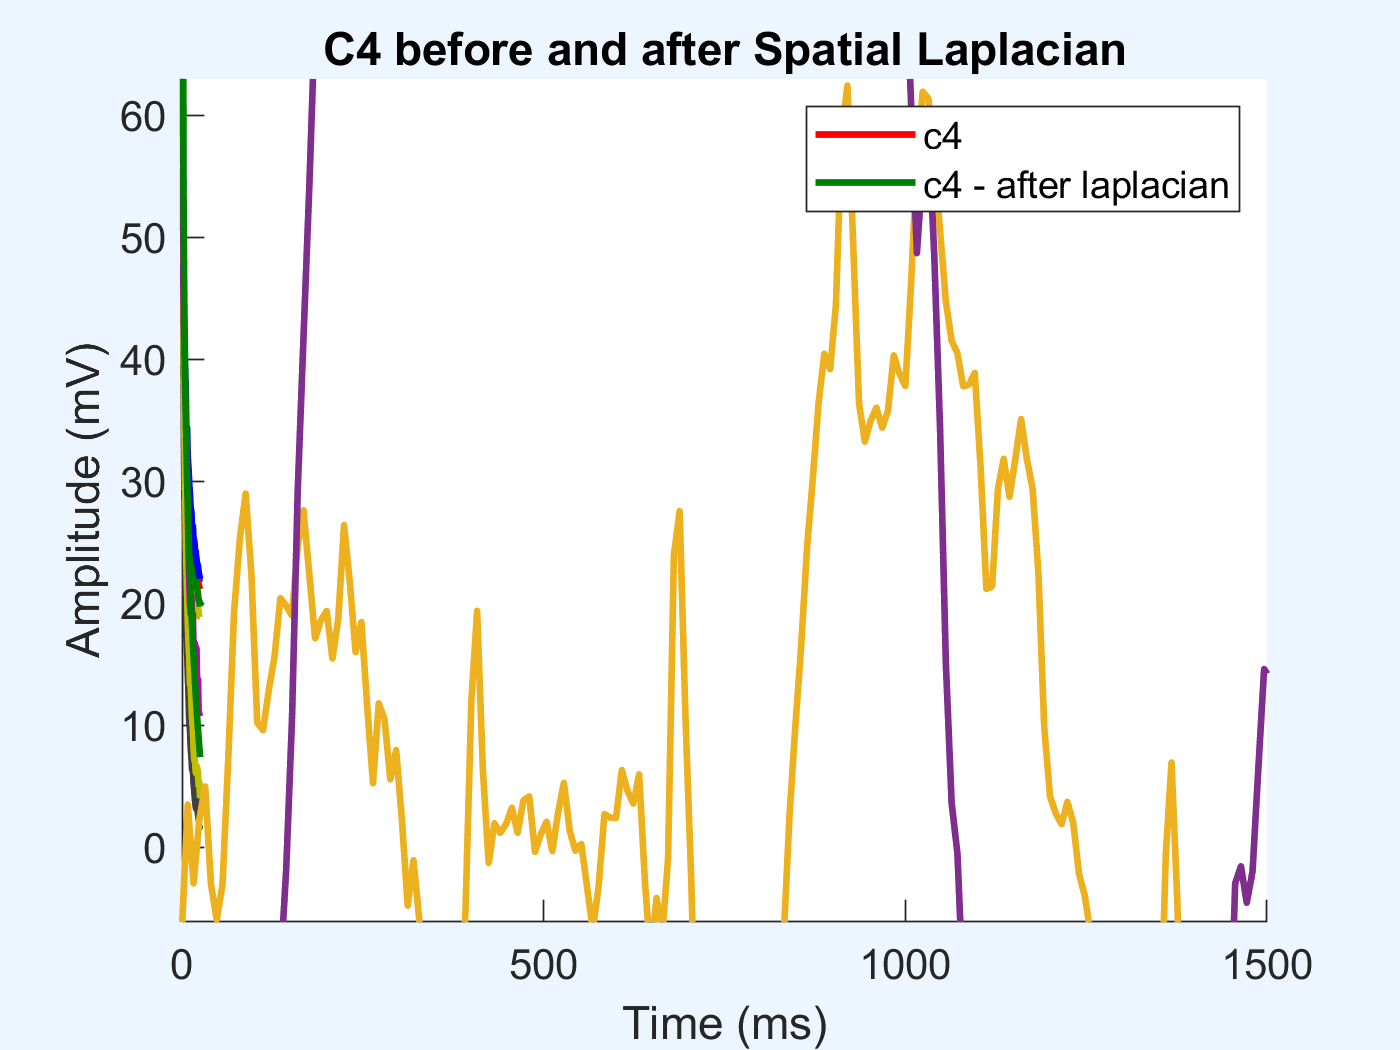

Topographic plot options ignored. First import a channel location file
To plot a single channel, use channel property menu or the following call
  >> figure; chan = 1; spectopo(EEG.data(chan,:,:), EEG.pnts, EEG.srate);


Pop_spectopo: finding data discontinuities
Selecting the first 50.0% of data for analysis...
Computing spectra (window length 125; fft length: 125; overlap 0):
................


Click on each trace for channel/component index


ans = 'figure; pop_spectopo(EEG, 1, [0  291952], 'EEG' , 'percent', 50, 'freqrange',[2 25],'electrodes','off');'

pop_spectopo(EEG_raw)


% plot cleaned data
eegplot(EEG_clean.data)


ans =

     []



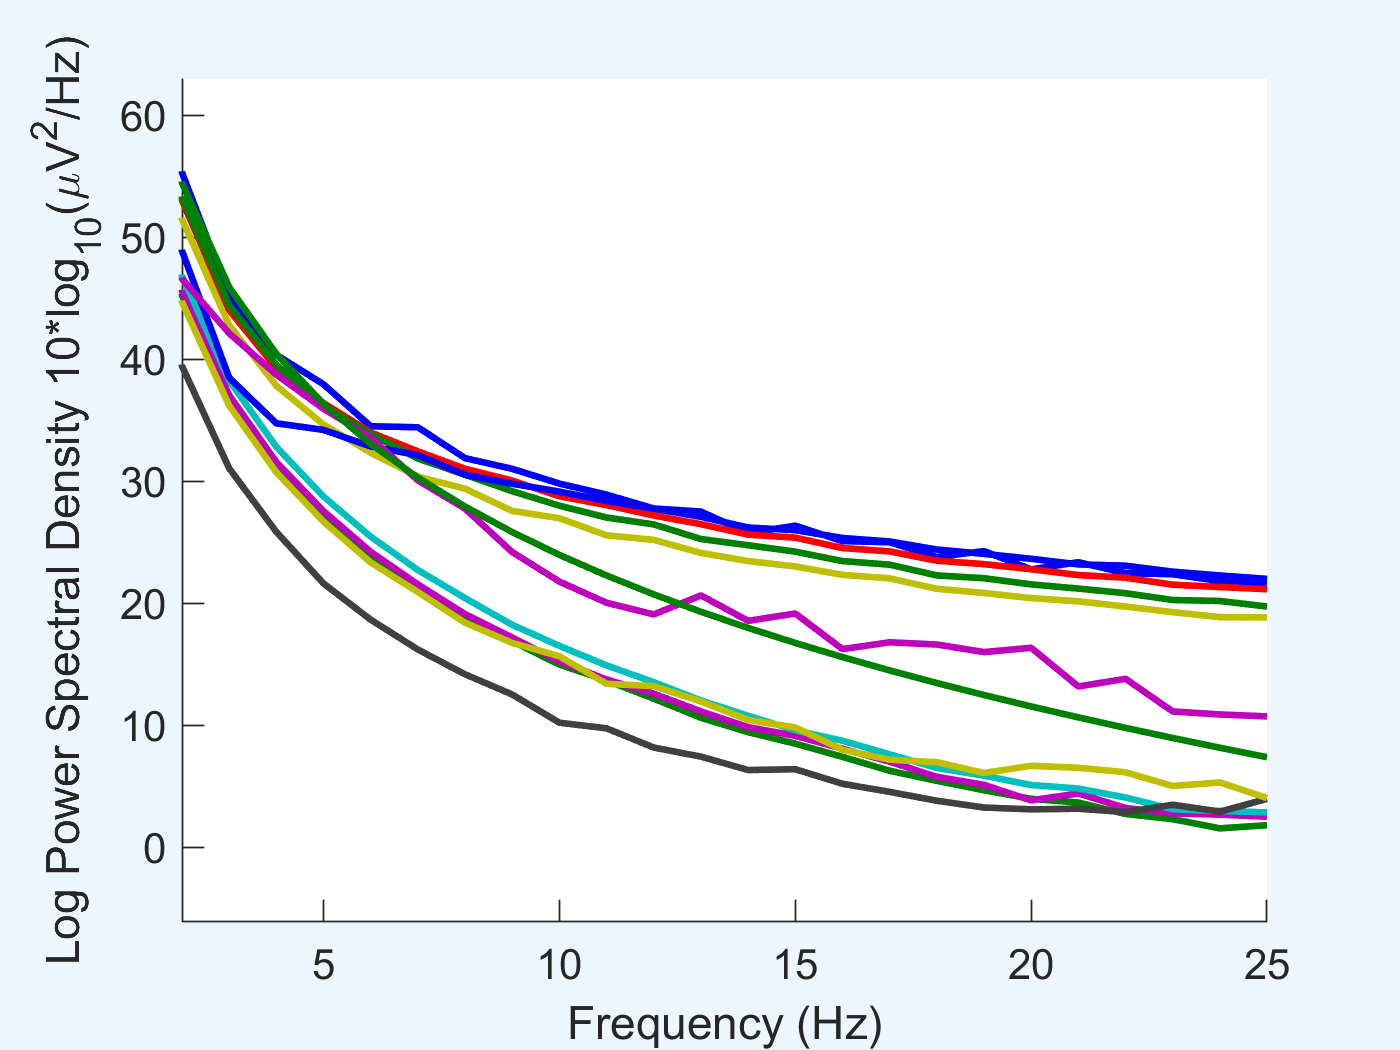

Topographic plot options ignored. First import a channel location file
To plot a single channel, use channel property menu or the following call
  >> figure; chan = 1; spectopo(EEG.data(chan,:,:), EEG.pnts, EEG.srate);


Pop_spectopo: finding data discontinuities
Selecting the first 50.0% of data for analysis...
Computing spectra (window length 125; fft length: 125; overlap 0):
................


Click on each trace for channel/component index


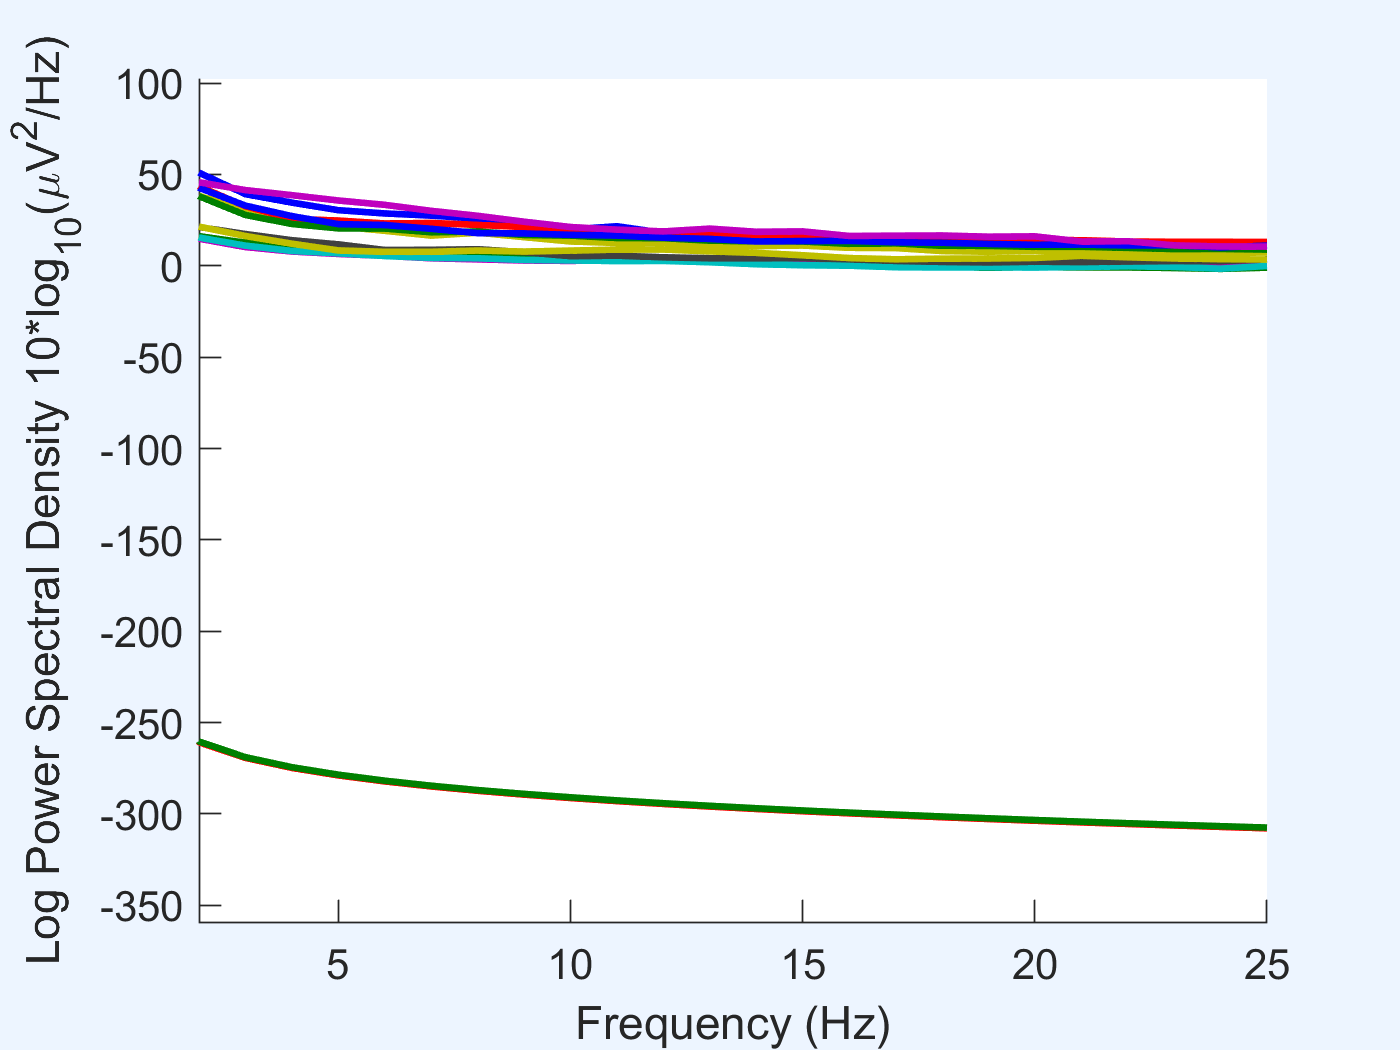

ans = 'figure; pop_spectopo(EEG, 1, [0  291952], 'EEG' , 'percent', 50, 'freqrange',[2 25],'electrodes','off');'

pop_spectopo(EEG_clean)